clc
clear

disp("Initilization Procedure")

Initilization Procedure


model.Parameters

param = control.calculateOperatingPoint(param);

Calculate Operating Point for T_a = 293.150000 [K]


param = model.calculateModel(param);

Calculate bilinear model matrices
Calculate linearisation decoupled
Calculate linearisation coupled
Testing controlability
Testing T_ref


simtime = 10*60;
A_JOHNogKarsten = cell(1,param.n)

A_JOHNogKarsten = 1×4 cell array
    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}


for i = 1:param.n
    A_JOHNogKarsten{i} = [-(param.ctrl.q_OP(i)/param.thermo.V_w(i) + param.thermo.B(i)/(param.thermo.C_w*param.thermo.rho_w*param.thermo.V_w(i))) param.thermo.B(i)/(param.thermo.C_w*param.thermo.rho_w*param.thermo.V_w(i)), 0;
                                param.thermo.B(i)/(param.thermo.C_a*param.thermo.rho_a*param.thermo.V_a(i)), -(param.ctrl.Q(i)/param.thermo.V_a(i) +param.thermo.B(i)/(param.thermo.C_a*param.thermo.rho_a*param.thermo.V_a(i))),0;
                                0, 1, 0];
end
param.model.A = blkdiag(A_JOHNogKarsten{:})

param = struct with fields:
    thermo: [1×1 struct]
      ctrl: [1×1 struct]
      pipe: [1×1 struct]
      pump: [1×1 struct]
     model: [1×1 struct]
         n: 4


eig(blkdiag(A_JOHNogKarsten{:}))

ans =          0
         0
         0
         0
   -4.0442
   -0.0312
   -0.0311
   -4.0059
   -0.0311
   -4.0059


%eig(param.model.A)



%param.model.A = -10*eye(12);
%param.model.B_Bar = blkdiag(ones(3,1),ones(3,1),ones(3,1),ones(3,1));
%param.model.B = blkdiag(ones(3,1),ones(3,1),ones(3,1),ones(3,1));
%param.model.B = ones(12,4);
%param.model.B_Bar = ones(12,4);

## Control

%param.ctrl.Ks = control.DesignProcedure1(param,0); 
param.ctrl.Ks = control.DesignProcedure2(param,0);

++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                Constraint|    Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Matrix inequality 12x12|   0.024977 to 8.0506|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++
++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                Constraint|    Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Matrix inequality 12x12|   0.024977 to 8.0506|
|   #2|   Matrix inequality 16x16|   0.012455 to 8.0506|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++


sol = struct with fields:
    yalmipversion: '20230622'
    matlabversion: '23.2.0.2409890 (R2023b) Update 3'
       yalmiptime: 0.0345
       solvertime: 0.0126
             info: 'Successfully solved (MOSEK-SDP)'
          problem: 0


K = 1.0e-04 *

   -0.0327    0.0039    0.0000         0         0         0         0         0         0         0         0         0
         0         0         0   -0.0891    0.0156    0.0000         0         0         0         0         0         0
         0         0         0         0         0         0   -0.2869    0.0571   -0.0000         0         0         0
         0         0         0         0         0         0         0         0         0   -0.0902    0.0131    0.0000


tau = 2.6929e+08

%param.ctrl.Ks = control.DesignProcedureFunky(param,0);
%param.ctrl.Ks = control.DesignRobust(param,0)

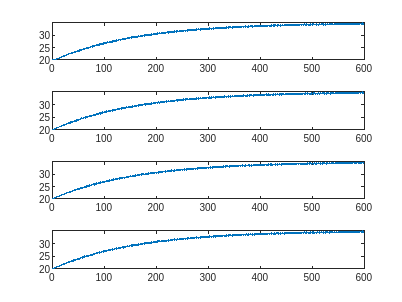

for i=1:4
    x0 = [param.ctrl.T_wOP(i); param.ctrl.T_aOP(i); 0];
    [t,x] = ode45(@(t,x)model.decoupledDynamics(t,x,i,param,200),[0 simtime],x0);
    decoupledResults(i).time = t;
    decoupledResults(i).Tw = x(:,1);
    decoupledResults(i).Ta = x(:,2);
    decoupledResults(i).T = x(:,3);
end
figure()
tiledlayout('vertical')
for i=1:4
    nexttile
    plot(decoupledResults(i).time,decoupledResults(i).Ta-273.15)
end

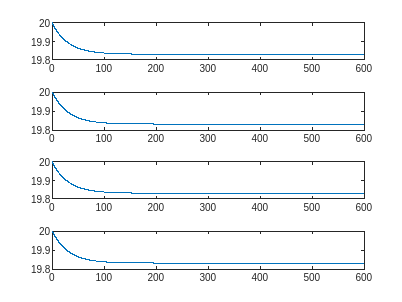

x0 = [param.ctrl.T_wOP.'; param.ctrl.T_aOP.'; zeros(4,1)];
options = odeset('RelTol',1e-8,'AbsTol',1e-10);
[t,x] = ode45(@(t,x)model.coupledDynamics(t,x,param,200),[0 simtime],x0,options);
coupledResults.time = t;
coupledResults.Tw = x(:,1:4);
coupledResults.Ta = x(:,5:8);
coupledResults.T = x(:,9:12);

figure()
tiledlayout('vertical')
for i=1:4
    nexttile
    plot(coupledResults.time,coupledResults.Ta(:,1)-273.15)
end